# Examples of linear superposition of LaserPulse objects

First laser pulse

% parameters
n = 2^12; dt = 0.1; s = 10; t0 = 10; f0 = 0.4;
t = (-n/2:n/2-1).' * dt;
et = exp(-(t-t0).^2/s^2 -2i*pi*t*f0);

% pulse initialization
p1 = LaserPulse(t, 'fs', et);

Second laser pulse

% modified parameters
et2 = exp(-(t-4*t0).^2/(2*s)^2 -2i*pi*t*(f0));
% pulse initialization
p2 = LaserPulse(t, 'fs', et2);

The sum of electric fields of the two laser pulses can be directly calculated:

psum = p1 + p2;

It is easy to plot the resulting pulse in either the time or the frequency domain:

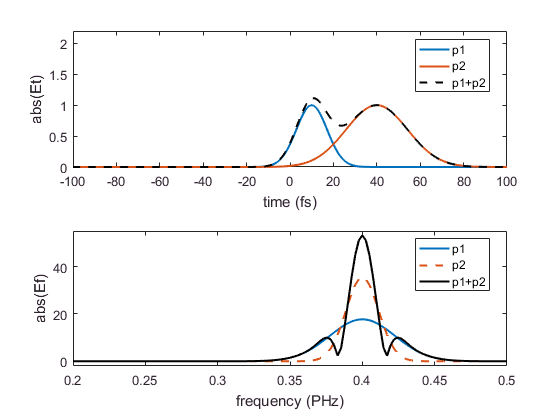

% create figure
figure()

% plots time domain
subplot(2,1,1)
plot(p1.timeArray,p1.temporalAmplitude, ...
  p2.timeArray, p2.temporalAmplitude, ...
  psum.timeArray, psum.temporalAmplitude,'k--', ...
  'LineWidth', 1.5);
xlabel(['time (', p1.timeUnits, ')']);
ylabel('abs(Et)');
legend('p1','p2','p1+p2','location','best');
axis([-100 100 0 2.2]);

% plots frequency domain
subplot(2,1,2)
plot(p1.frequencyArray,p1.spectralAmplitude,'-', ...
  p2.frequencyArray, p2.spectralAmplitude,'--', ...
  psum.frequencyArray, psum.spectralAmplitude,'k-', ...
  'LineWidth', 1.5);
xlabel(['frequency (', p1.frequencyUnits, ')']);
ylabel('abs(Ef)');
legend('p1','p2','p1+p2','location','best');
axis([0.2 0.5 -2 55])